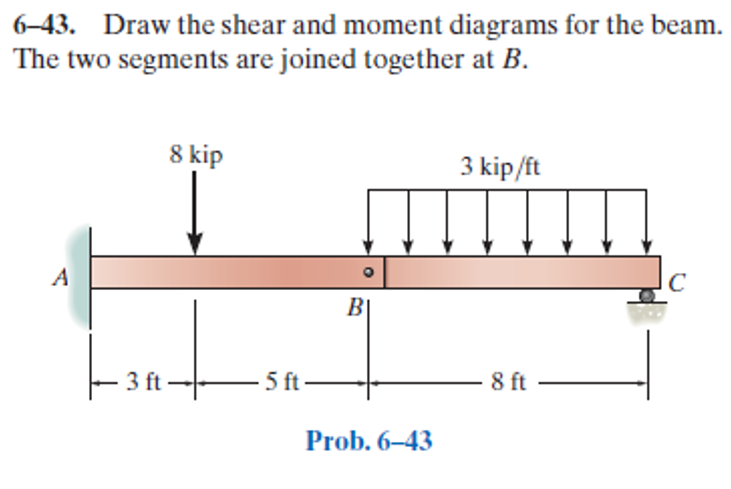

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-43P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-43P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'moment', 'Ma', 0);
b = b.add('concentrated', 'force', -8*u.kip, 3*u.ft);
b = b.add('hinge', 'force', 'Hb', 8*u.ft);
b = b.add('reaction', 'force', 'Rc', 16*u.ft);
b = b.add('distributed', 'force', -3*u.kip/u.ft, [8 16]*u.ft);
b.L = 16*u.ft;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} \frac{10\,x^{2}\,\left(x-18\,\mathrm{ft}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\leq 3\,\mathrm{ft}\\ -\frac{2\,\left(-x^{3}+24\,x^{2}\,\mathrm{ft}+18\,x\,{\mathrm{ft}}^{2}-18\,{\mathrm{ft}}^{3}\right)}{\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(3\,\mathrm{ft},8\,\mathrm{ft}\right]\\ -\frac{\left(x-16\,\mathrm{ft}\right)\,\left(x^{3}-32\,x^{2}\,\mathrm{ft}+256\,x\,{\mathrm{ft}}^{2}-2812\,{\mathrm{ft}}^{3}\right)}{8\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{10\,x\,\left(x-12\,\mathrm{ft}\right)}{\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\leq 3\,\mathrm{ft}\\ -\frac{6\,\left(-x^{2}+16\,x\,\mathrm{ft}+6\,{\mathrm{ft}}^{2}\right)}{\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(3\,\mathrm{ft},8\,\mathrm{ft}\right]\\ -\frac{x^{3}-36\,x^{2}\,\mathrm{ft}+384\,x\,{\mathrm{ft}}^{2}-1727\,{\mathrm{ft}}^{3}}{2\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 20\,\left(x-6\,\mathrm{ft}\right)\,\mathrm{kip} & \text{ if }x\leq 3\,\mathrm{ft}\\ 12\,\left(x-8\,\mathrm{ft}\right)\,\mathrm{kip} & \text{ if }x\in \left(3\,\mathrm{ft},8\,\mathrm{ft}\right)\\ -\frac{3\,\left(x-8\,\mathrm{ft}\right)\,\left(x-16\,\mathrm{ft}\right)}{2}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }8\,\mathrm{ft}\leq x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 20\,\mathrm{kip} & \text{ if }x\leq 3\,\mathrm{ft}\\ 12\,\mathrm{kip} & \text{ if }x\in \left(3\,\mathrm{ft},8\,\mathrm{ft}\right)\\ -3\,\left(x-12\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }8\,\mathrm{ft}\leq x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<8\,\mathrm{ft}\\ -3\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }8\,\mathrm{ft}\leq x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ma} & 120\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Ra} & 20\,\mathrm{kip}\\ \mathrm{Rc} & 12\,\mathrm{kip} \end{array}\right)$$

ha

$$ha = \left(\begin{array}{cc} \mathrm{Hb} & -12\,\mathrm{kip} \end{array}\right)$$

# shear and moment diagram

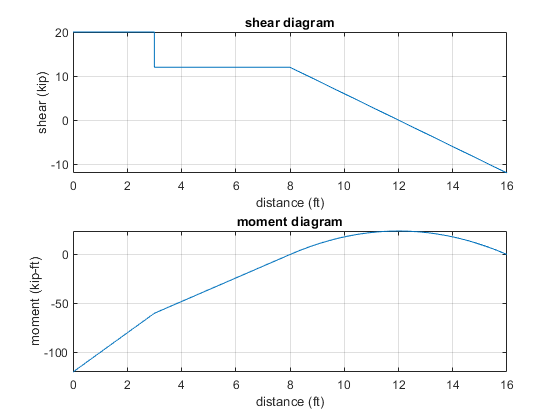

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;